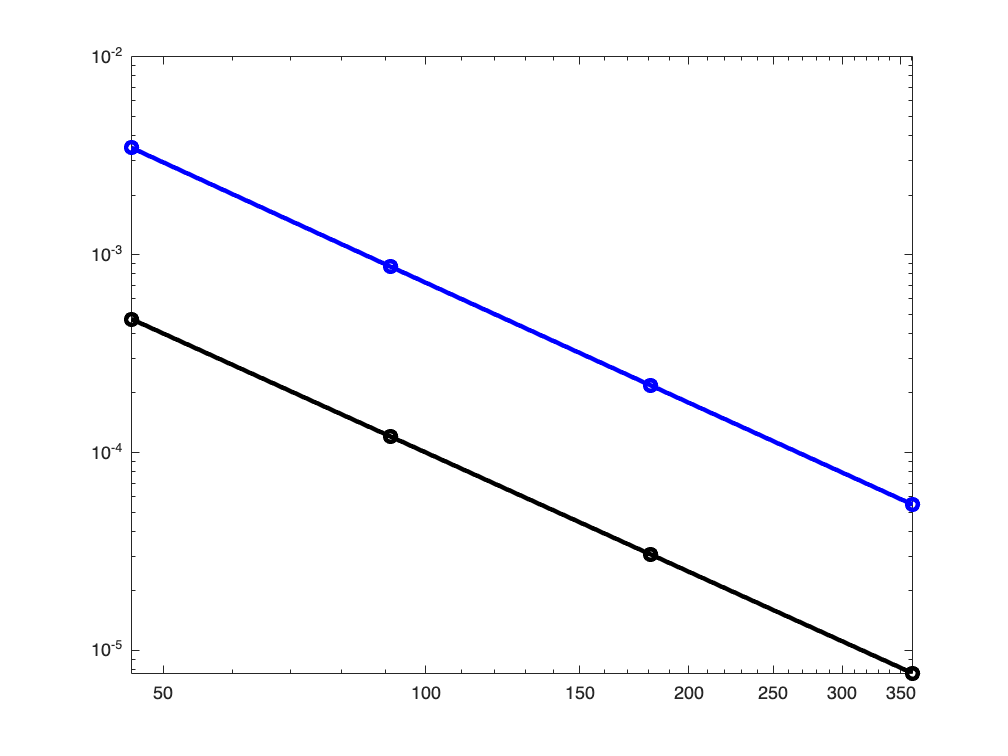

t0 = 1;
tF = 10;
y =@(t) 2.*(t.^(1./3)) - log(t) - 4;



a =@(t) 1/(3.*t);
b =@(t) (log(t)+1)/(3*t);
f =@(t,y) y./(3.*t)+(log(t)+1)./(3.*t);
y0 = -2;
h = 1/5;
timestep = [1/5, 1/10, 1/20, 1/40];
ns = zeros(1,4);
errorcn = zeros(1,4);
errorimp = zeros(1,4);
errorexp = zeros(1,4);
errorrn = zeros(1,4);
errorhn = zeros(1,4);
errorrk4 = zeros(1,4);
for i=1:4
    [th, uh] = crank_nicolson(a, b, t0, tF, y0,  timestep(1,i));
    y_sol = y(th);
    errorcn(1,i) = max(abs(y_sol-uh));
    [th, uh] = implicit_euler(a, b, t0, tF, y0,  timestep(1,i));
    errorimp(1,i) = max(abs(y_sol-uh));
    [th, uh] = explicit_euler(f, t0, tF, y0,  timestep(1,i));
    errorexp(1,i) = max(abs(y_sol-uh));
    [th, uh] = runge_method(f, t0, tF, y0,  timestep(1,i));
    errorrn(1,i) = max(abs(y_sol-uh));
    [th, uh] = heun_method(f, t0, tF, y0,  timestep(1,i));
    errorhn(1,i) = max(abs(y_sol-uh));
    [th, uh] = rk4_method(f, t0, tF, y0,  timestep(1,i));
    errorrk4(1,i) = max(abs(y_sol-uh));
    ns(1,i) = length(th);
end

loglog(ns,errorcn,"o-b",'LineWidth', 2.5)
hold on;
bound = ns.^(-2);
loglog(ns,bound,"o-k",'LineWidth', 2.5)
hold off;

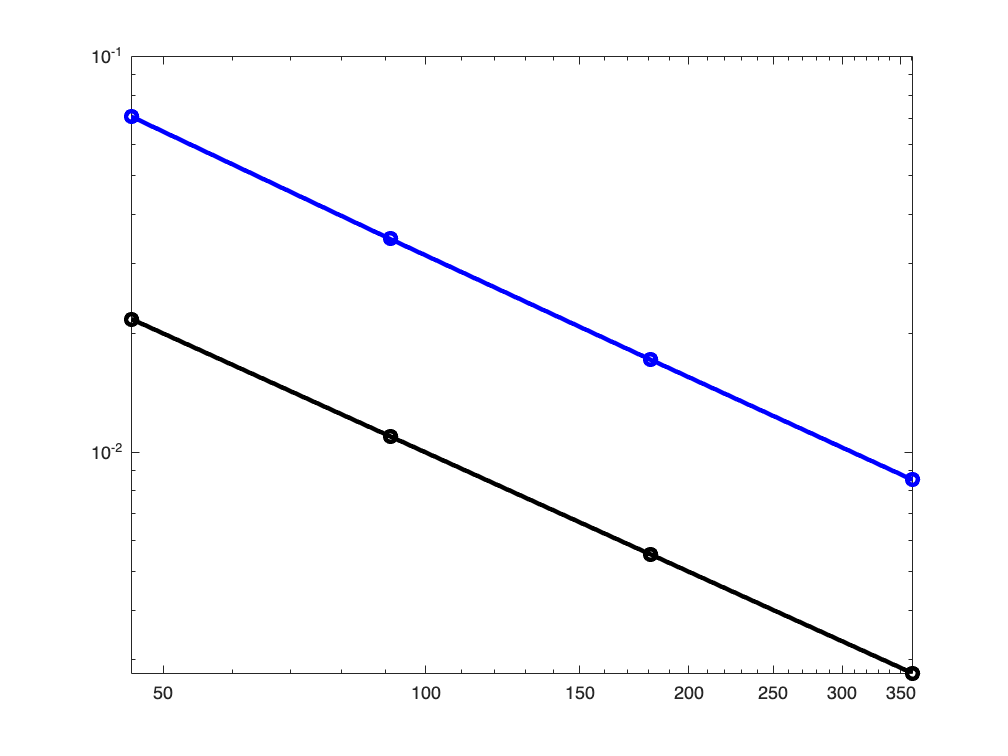

loglog(ns,errorexp,"o-b",'LineWidth', 2.5)
hold on;
bound = ns.^(-1);
loglog(ns,bound,"o-k",'LineWidth', 2.5)
hold  off;

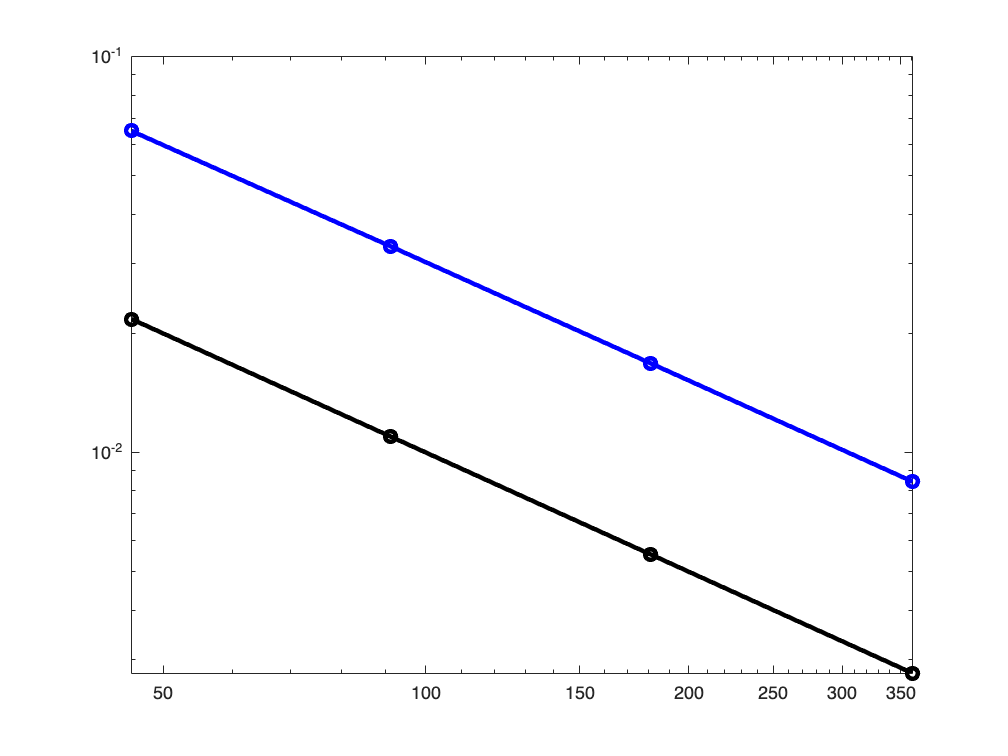

loglog(ns,errorimp,"o-b",'LineWidth', 2.5)
hold on;
bound = ns.^(-1);
loglog(ns,bound,"o-k",'LineWidth', 2.5)
hold  off;

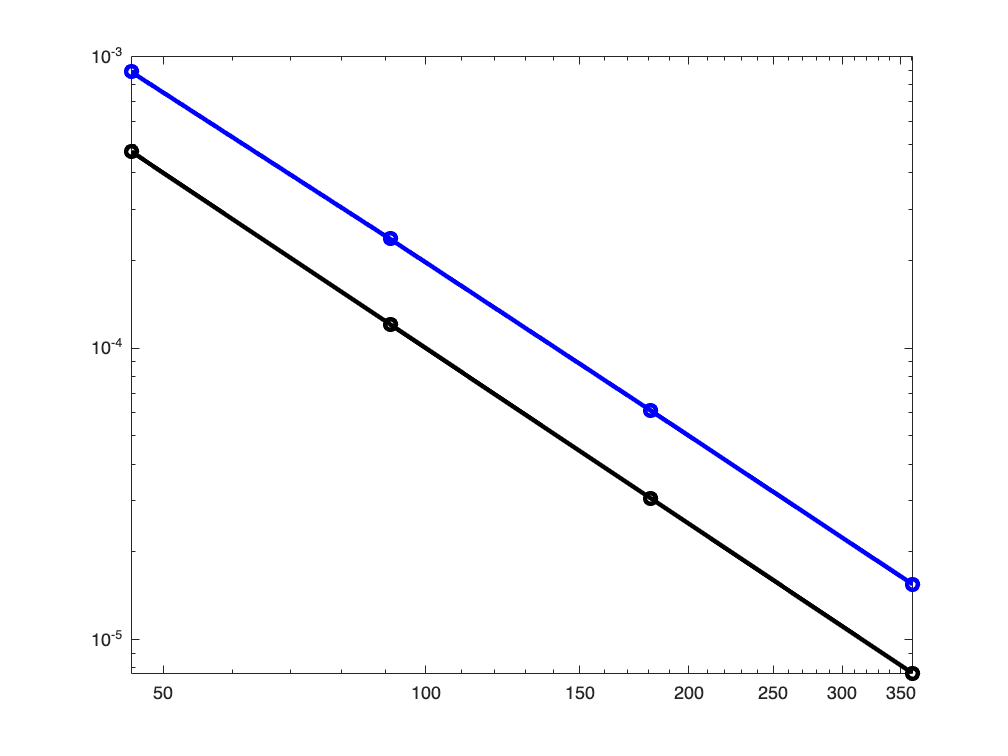

loglog(ns,errorrn,"o-b",'LineWidth', 2.5)
hold on;
bound = ns.^(-2);
loglog(ns,bound,"o-k",'LineWidth', 2.5)
hold  off;

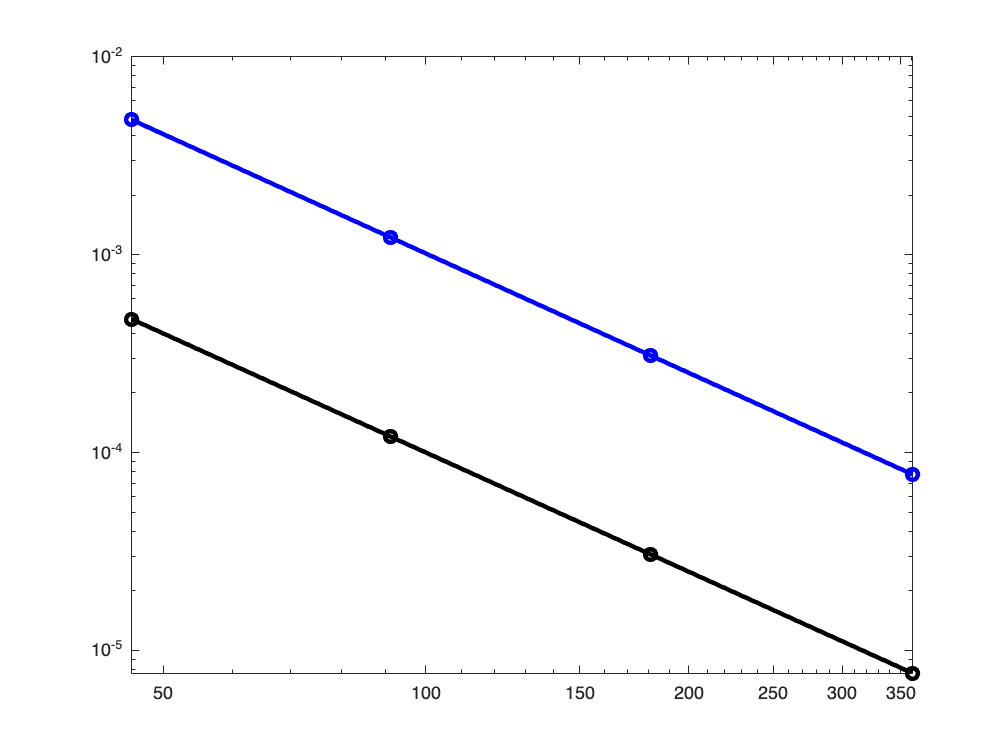

loglog(ns,errorhn,"o-b",'LineWidth', 2.5)
hold on;
bound = ns.^(-2);
loglog(ns,bound,"o-k",'LineWidth', 2.5)
hold  off;

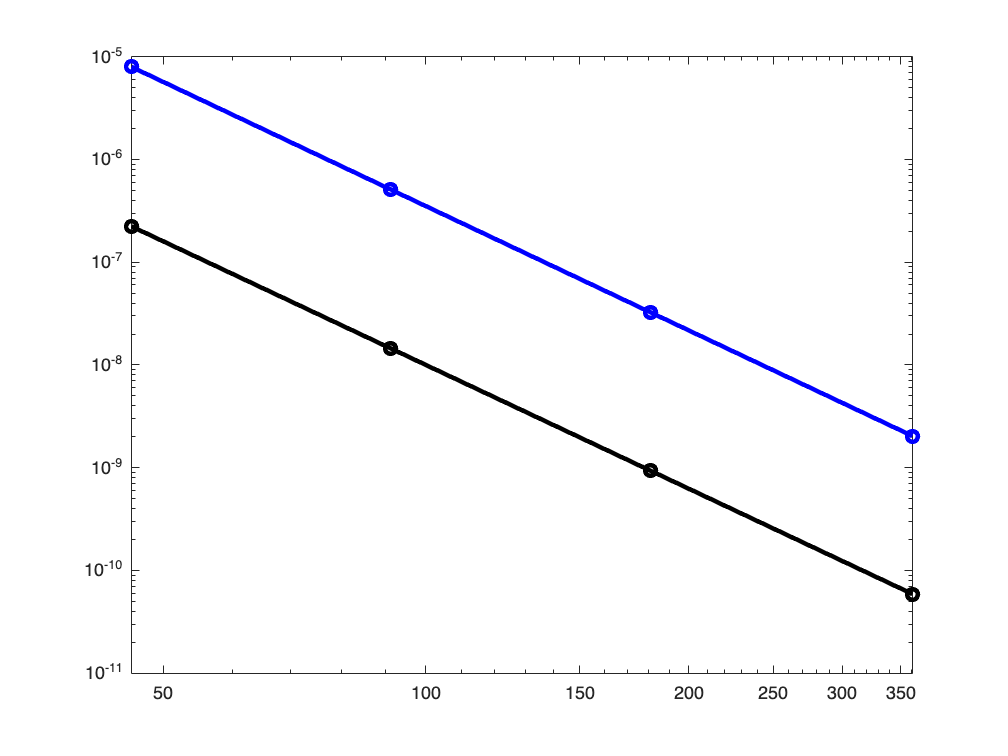

loglog(ns,errorrk4,"o-b",'LineWidth', 2.5)
hold on;
bound = ns.^(-4);
loglog(ns,bound,"o-k",'LineWidth', 2.5)
hold  off;